# 需求分析：曲面裁剪

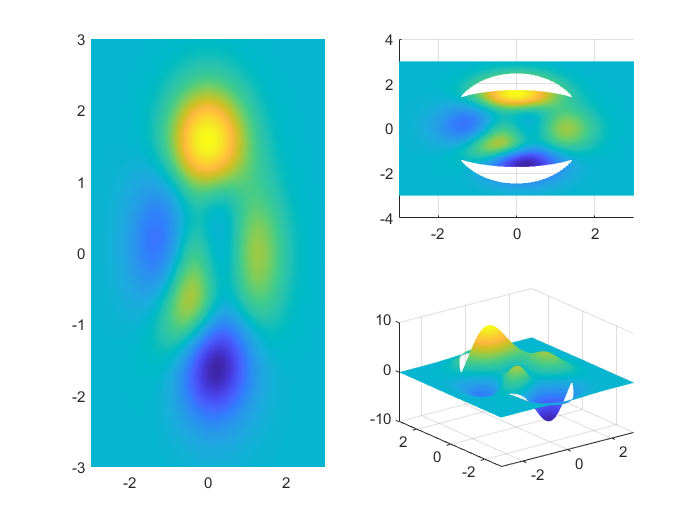

clear; clc;
% 生成多峰图
n = 300;
[x, y, z] = peaks(n);
% 绘制原图
subplot(2, 2, [1,3])
surf(x, y, z);
xlim([-3, 3]);
ylim([-3, 3]);
shading interp
view(0, 90)
% 裁剪
for i = 1:n
    for j = 1:n
        if x(i, j)^2 + 2 * y(i, j)^2 > 6 && 2 * x(i, j)^2 + y(i, j)^2 < 6
            z(i, j) = NaN;
        end
    end
end
subplot(2, 2, 2)
surf(x, y, z);
xlim([-3, 3]);
shading interp
view(0, 90)
subplot(2, 2, 4)
surf(x, y, z);
shading interp

% view(0, 90)